clear;

Consider the observed set of points of the form (x, y) ∈ R 2 in the file "points2D_Set1.mat". 

Assume each observation (x, y) is drawn independently from the joint probability density function P(X, Y ) of random variables X and Y . For this question, you cannot use the functions mean(), cov(), and pca() in Matlab.

load("points2D_Set1.mat");


 • (5 points) How can principal component analysis (PCA) be used to best approximate a linear rela�tionship between random variables X and Y . Describe the method clearly, using appropriate math�ematical descriptions for clarity. Your description should be clear enough to lead to a programmable implementation. 

take from slides..

a direction v along which variance of points is maximised

shift the distribution by its mean

result: argmax v:||v||=1 v'Cv

C = QDQ'

argmax w:||w||=1 w'Dw 

take w as unit vector along max `eigenvalue`|

and Qw = v

required line: a(Qw) + mean

• (5 points) Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. 

xm = sum(x)/length(x);
ym = sum(y)/length(y);
p = [x';y'];
%sample cov
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1);

[Q,D] = eig(cov);
D = abs(diag(D));
w = D==max(D) ; %would have to do more when two have equal, could 2 be equal tho?
v=Q*w %+ [xm,ym]

v =     0.5247
    0.8513


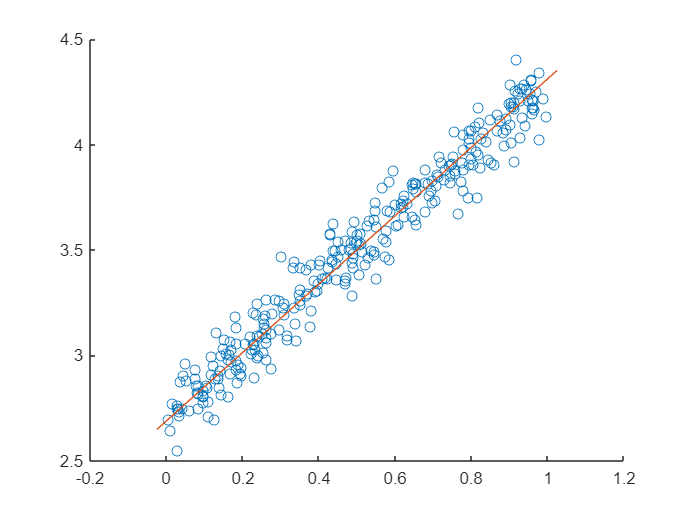

scatter(x,y); hold on;
%improve this lol, abhi jugaad hai
plot(linspace(-1,1,10)*(v(1))+xm,linspace(-1,1,10)*(v(2))+ym)
hold off;

• (5 points) Repeat the same analysis for the set of points in "points2D_Set2.mat". Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. Compared to the result on the other set of points, justify the quality of the approximation resulting in this question using logical arguments. 

load("points2D_Set2.mat");
xm = sum(x)/length(x);
ym = sum(y)/length(y);
p = [x';y'];
%sample cov
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1);

[Q,D] = eig(cov);
D = abs(diag(D));
w = D==max(D) ; %would have to do more when two have equal, could 2 be equal tho?
v=Q*w %+ [xm,ym]

v =    -0.9999
   -0.0162


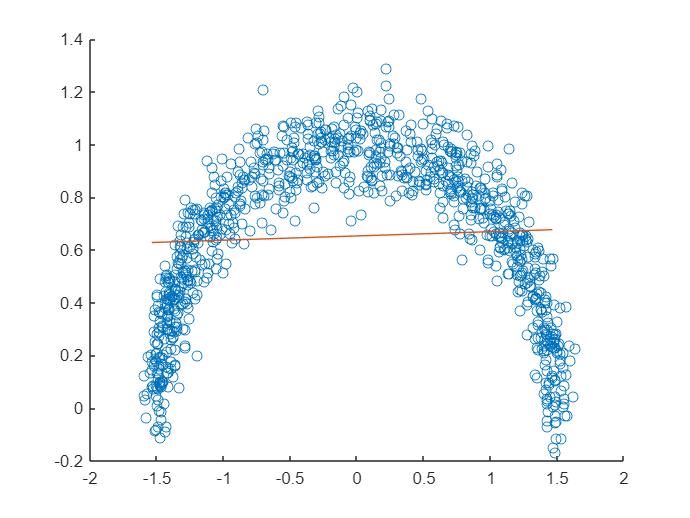

scatter(x,y); hold on;
%improve this lol, abhi jugaad hai
plot(linspace(-1.5,1.5,10)*(v(1))+xm,linspace(-1.5,1.5,10)*(v(2))+ym)
hold off;